# Example 2: Arrays

Arrays of `UncVal` objects can be created and plotted.

## Creating Arrays

Arrays of `UncVal` objects can be created by passing an array input to the constructor

x = UncVal(linspace(0, 1, 8), 0.02, "x");
a = UncVal(0, 0.04, "a");
y = x.^2 + a;
disp(y)

  1×8 UncVal array with properties:

        val: [0 0.0204 0.0816 0.1837 0.3265 0.5102 0.7347 1]
         id: "calc"
    uncType: "1-sigma"
    std_unc: [0.0400 0.0404 0.0416 0.0435 0.0461 0.0492 0.0527 0.0566]



Elements can be accessed like a normal array.

disp(x(2))

  UncVal with properties:

         val: 0.1429
          id: "x"
     uncType: "1-sigma"
     std_unc: 0.0200
    var_srcs: [1×6 table]



Arrays can be concatenated, transposed, and reshaped as expected.

xcat = [UncVal([0, 1], 0.1, "xc1"), UncVal([2, 3], 0.2, "xc2")]

xcat = 1×4 UncVal array with properties:
        val: [0 1 2 3]
         id: "calc"
    uncType: "1-sigma"
    std_unc: [0.1000 0.1000 0.2000 0.2000]


xtranspose = xcat'

xtranspose = 4×1 UncVal array with properties:
         val: [4×1 double]
          id: "calc"
     uncType: "1-sigma"
     std_unc: [4×1 double]
    var_srcs: [2×6 table]


xreshape = reshape(xcat, 2, [])

xreshape = 2×2 UncVal array with properties:
        val: [2×2 double]
         id: "calc"
    uncType: "1-sigma"
    std_unc: [2×2 double]


## Plotting Arrays

Arrays can be sent directly to the `plot` and `errorbar` commands.  The `plot` command will only plot the nominal values.  The `errorbar` command will plot uncertainty in `x` or `y` if an `UncVal` object is passed.  If both `x` and `y` are `UncVal` objects, then the correlated uncertainty is plotted as the standard deviational ellipse.  Error bars are drawn at at 95.54% confidence ($2\sigma \;$in the 1D case).

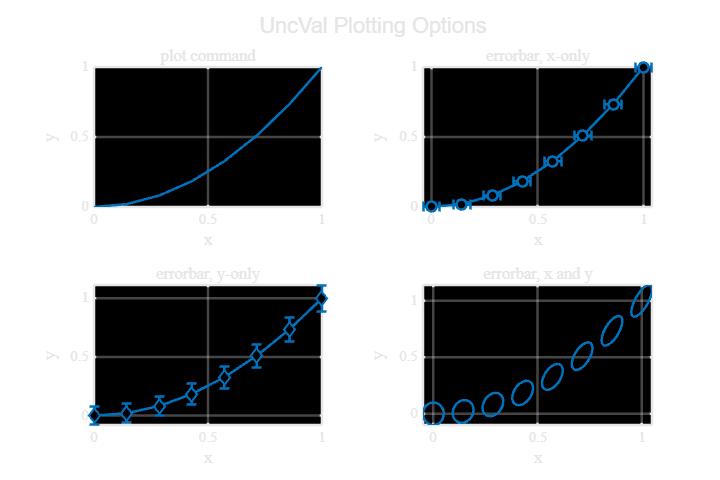

figure("defaultErrorBarLineWidth", 1.5, ...
    "Units", "in", "Position", [1,1,6,4]);
t = tiledlayout("flow");
title(t, "UncVal Plotting Options");
nexttile;hold on;xlabel("x");ylabel("y");
title("plot command", FontWeight="normal");
plot(x, y);

t.Title.Color = get(gca, "XColor"); % I have some funny defaults
t.Title.FontName = get(gca, "FontName");

ha = nexttile;hold on;xlabel("x");ylabel("y");
title("errorbar, x-only", FontWeight="normal")
errorbar(x, y.val, Marker="o");

nexttile;hold on;xlabel("x");ylabel("y");
title("errorbar, y-only", FontWeight="normal")
errorbar(x.val, y, Marker="d");

nexttile;hold on;xlabel("x");ylabel("y");
title("errorbar, x and y", FontWeight="normal")
errorbar(x, y);

## Functions that Reduce an Array

Many functions that normally reduce an array, do not reduce arrays of `UncVal` objects.  These functions can be thought of as acting on the distribution in the `UncVal` object, and not on the array.  For example, the `mean` and `std` functions, return the mean and standard deviation of the underlying distributions.  The array returned is the same size as the `UncVal` array.

disp(x)

  1×8 UncVal array with properties:

        val: [0 0.1429 0.2857 0.4286 0.5714 0.7143 0.8571 1]
         id: "x"
    uncType: "1-sigma"
    std_unc: [0.0200 0.0200 0.0200 0.0200 0.0200 0.0200 0.0200 0.0200]



disp(mean(x))

         0    0.1429    0.2857    0.4286    0.5714    0.7143    0.8571    1.0000



disp(std(x))

    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200



The `sum` function will reduce an array, but the statistical independence of the arguments must be considered.  The average of multiple values have less uncertainty if they are statistically independent, this is not true if they are statistically dependent.  Note that $1\sigma \;$uncertainties are input to the constructors, but the $2\sigma \;$value is displayed in the string.

xind = [UncVal(1, 0.1, "x1"), UncVal(2, 0.1, "x2")];
disp("average of xind = " + string(sum(xind)/length(xind)));

average of xind = UncVal (id=calc): 1.5 ± 0.141421 (2-sigma)


xdep = UncVal([1, 2], 0.1, "x");
disp("average of xdep = " + string(sum(xdep)/length(xdep)));

average of xdep = UncVal (id=calc): 1.5 ± 0.2 (2-sigma)
